Pruebas de tiempo

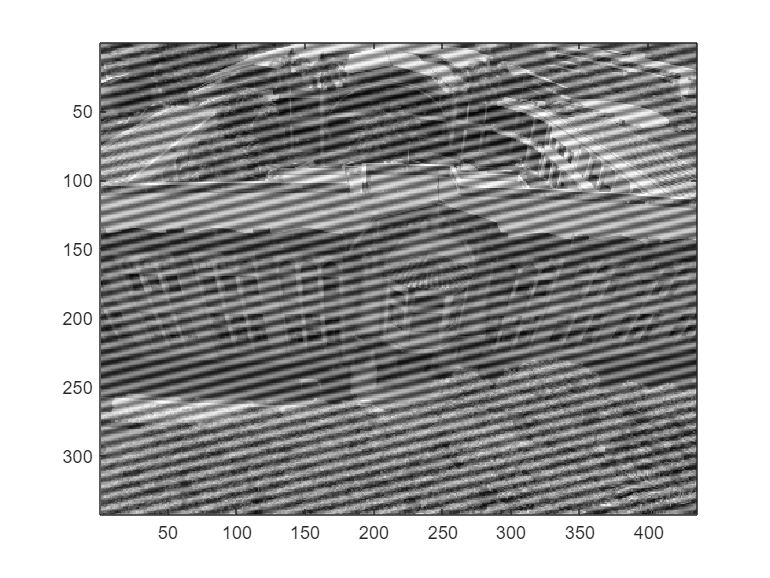

noise =rgb2gray(imread("NoiseImage.png"));
colormap("gray")

imagesc(noise)

tic
dftNoise = DFT_selfMade(noise);
toc
imagesc(log(abs(fftshift(dftNoise))))

tic
fftNoise = fft2(noise);
toc
imagesc(log(abs(fftshift(fftNoise))))

Pruebas de espectro angular

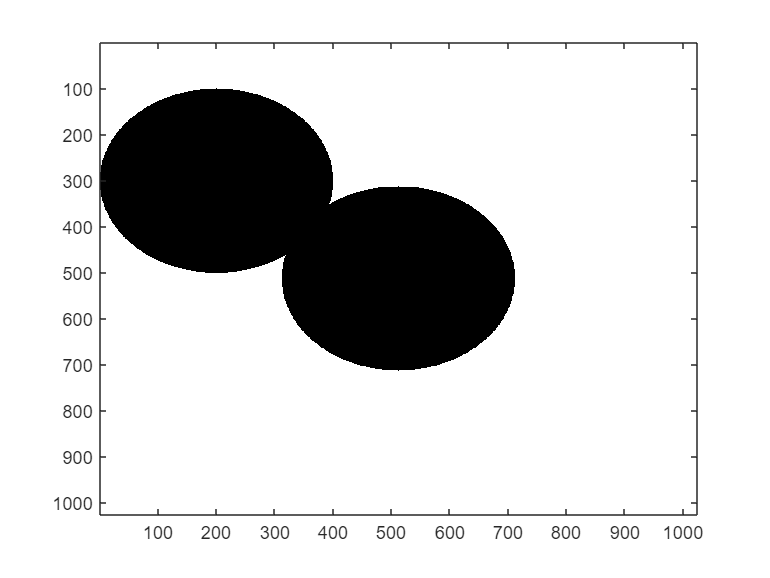

% Tamaño
Nx = 1024;
Ny = 1024;
% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

% Cambio
dx = 1*um;
dy = 1*um;

z = 50*mm;

waveLength = 650*nm;

radio = 20;
transmitancia = ~filtroCircular([Ny/2 Nx/2; 200 300],[10*radio, 10*radio],[Ny Nx]);
imagesc(transmitancia)

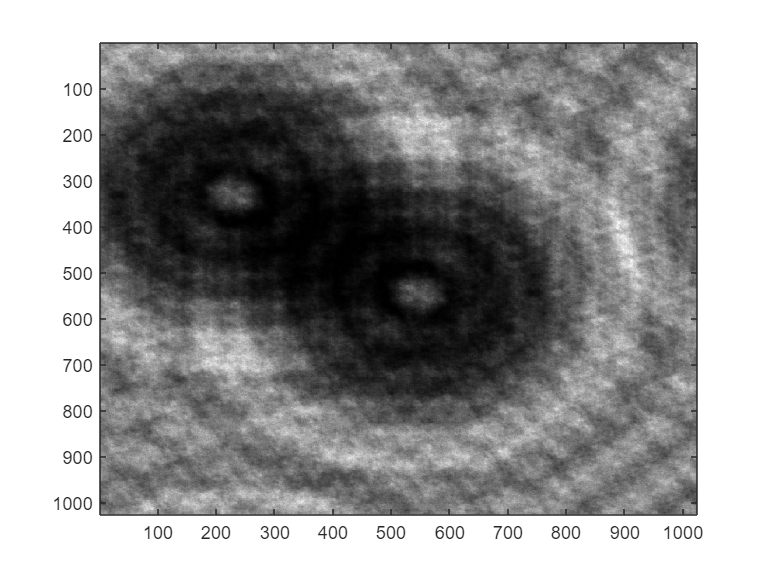

transmitanciaProp = espectroAngular(transmitancia,dx,dy,z,waveLength,"dft",false);
imagesc(abs(transmitanciaProp).^2)